# TP2

## 3.1 Implémentation de système discret (FIR/IIR)

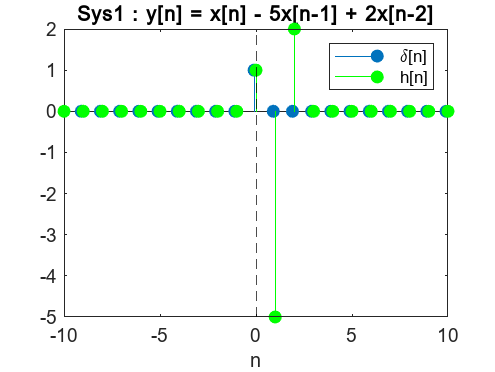

clear; clc; close all;
format default; format compact;


% Impulsion de dirac
n = -10:10;
deltaVal = delta(n);
stem(n - 0.1, deltaVal, 'filled');

% y[n]
h1 = sys1(deltaVal);
hold on; stem(n, h1, 'g', 'filled');
xlim([-10 10]);
xline(0, 'k--');
xlabel('n');
legend(["\delta[n]","h[n]"]);
title('Sys1 : y[n] = x[n] - 5x[n-1] + 2x[n-2]');

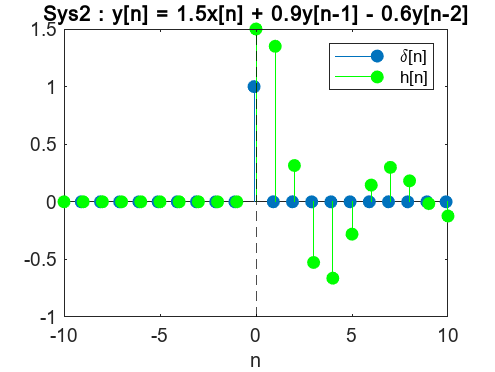


% Le système est stable car il retourne à 0
% Il est avec mémoire comme en n=2, il dépends de la valeur en n=0
% Il est causal car il ne dépends pas de valeur de n futures

% Sys2 : y[n] = 1.5x[n] +0.9x[n-1] -0.6x[n-2]
h2 = sys2(deltaVal);
figure;
stem(n - 0.1, deltaVal, 'filled');
hold on; stem(n, h2, 'g', 'filled');
xlim([-10 10]);
xline(0, 'k--');
xlabel('n');
legend(["\delta[n]","h[n]"]);
title('Sys2 : y[n] = 1.5x[n] + 0.9y[n-1] - 0.6y[n-2]');


% A première vue le système à l'air stable car il se rapproche de 0.
% Il est causal (pas de valeurs n<0) et avec mémoire (valeurs n>0)
% Ordre ? 

## 3.2 Réponse de systèmes discrets et convolution

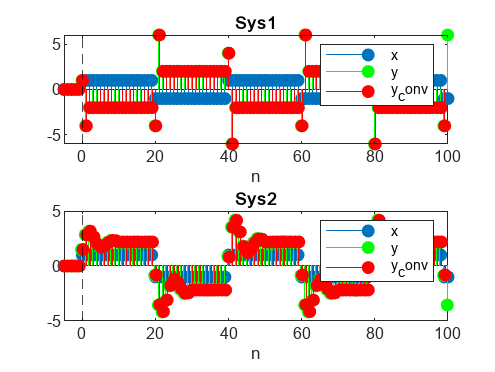


n = -100:100;
u = cumsum(delta(n));
x = square(n/(2*pi)).*u; % Signal carré pulsé démarrant en n=0

% Sys1
y1 = sys1(x);

% Sys2
y2 = sys2(x);

% Par réponses impulsionnelles : (générées dans la section précédente,
% faire un Run ALL)

% y[n] = x[n] ** h[n]
% La fonction conv fait la convolution des deux signaux et a une paramètre
% shape. Si 'same', la taille reste la meme que x.
y1_c = conv(x, h1, 'same');
y2_c = conv(x, h2, 'same');


% Plot de tout :
% Pour Sys1
figure;
subplot(211);
stem(n, x, 'filled');
hold on; stem(n - 0.1, y1, 'g', 'filled');
hold on; stem(n + 0.1, y1_c, 'r', 'filled');
xlim([-5 100]);
xline(0, 'k--');
xlabel('n');
legend(["x", "y", "y_conv"]);
title('Sys1');

% % Pour Sys2
% figure;
subplot(212);
stem(n, x, 'filled');
hold on; stem(n - 0.2, y2, 'g', 'filled');
hold on; stem(n + 0.2, y2_c, 'r', 'filled');
xlim([-5 100]);
xline(0, 'k--');
xlabel('n');
legend(["x", "y", "y_conv"])
% legend(["x", "y_1", "y_{1conv}", "y_2", "y_{2conv}"]);
title('Sys2');

% title('Convolution');

% Les deux signaux générés sont bel et bien identiques. 